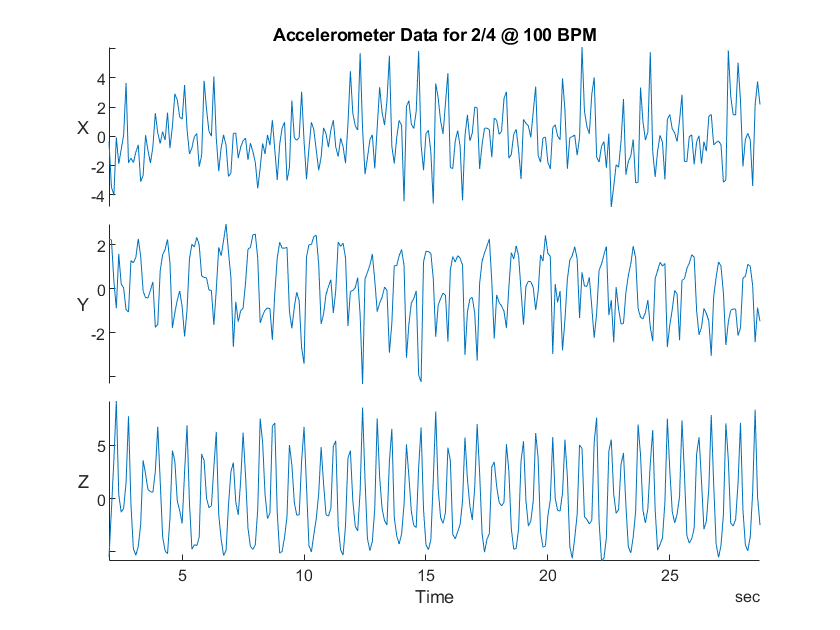

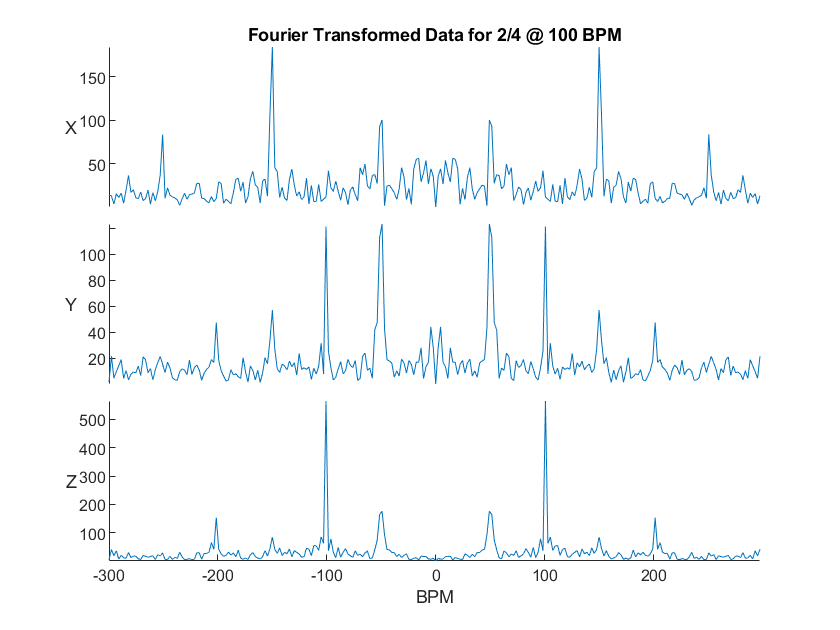

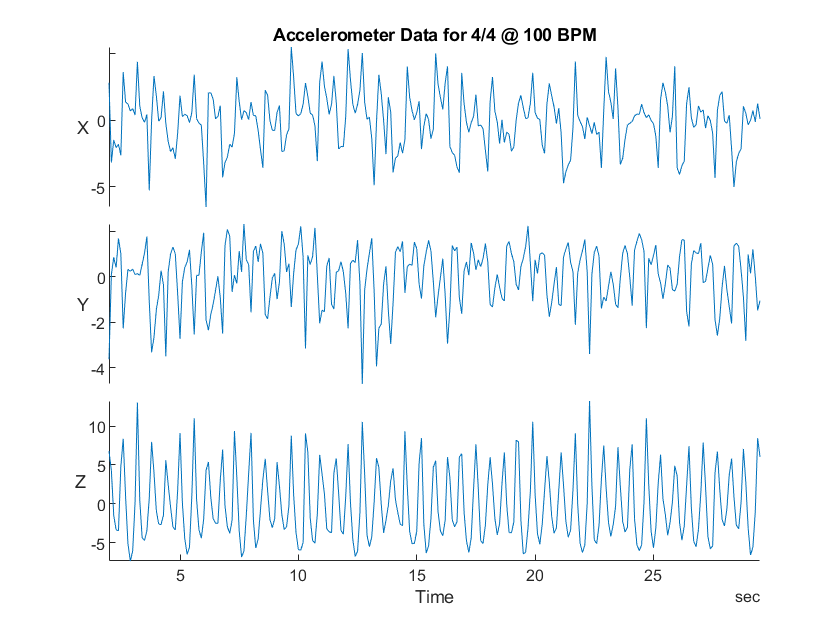

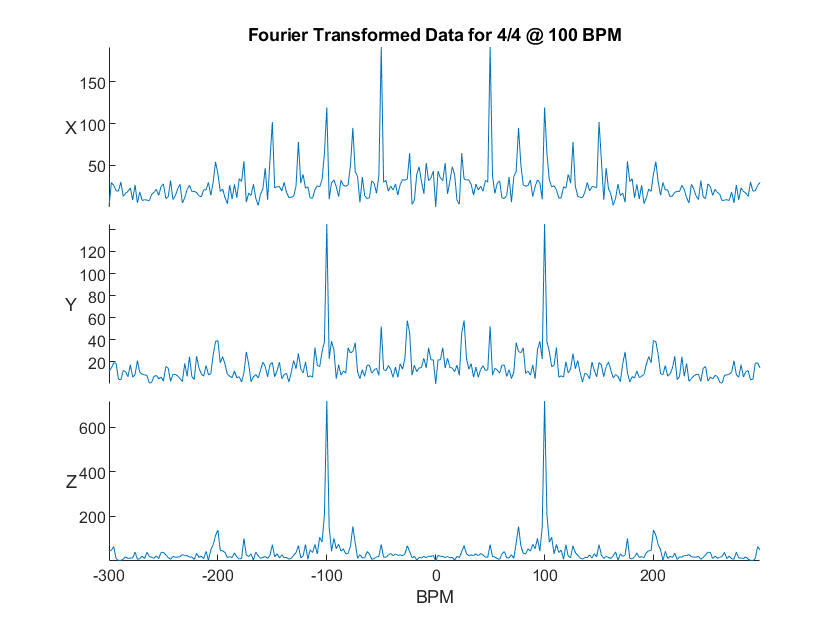

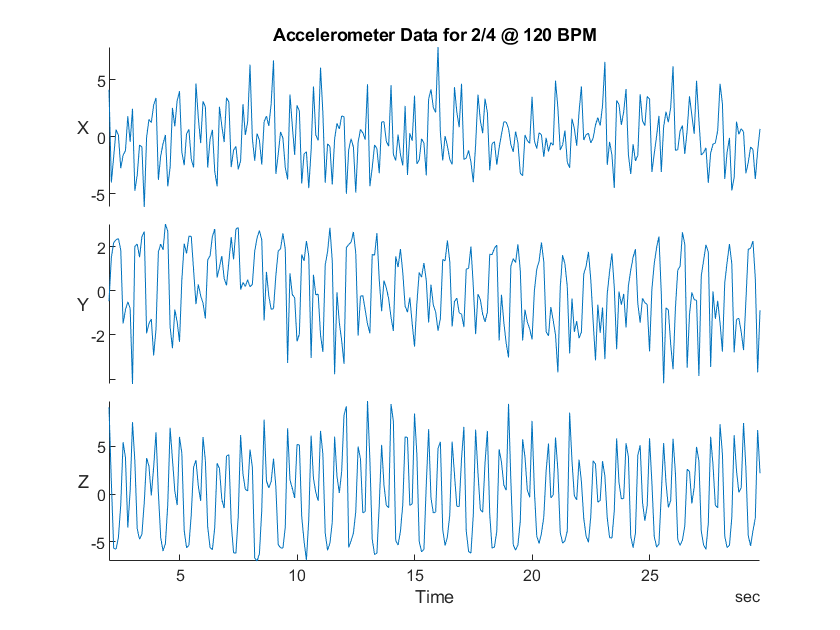

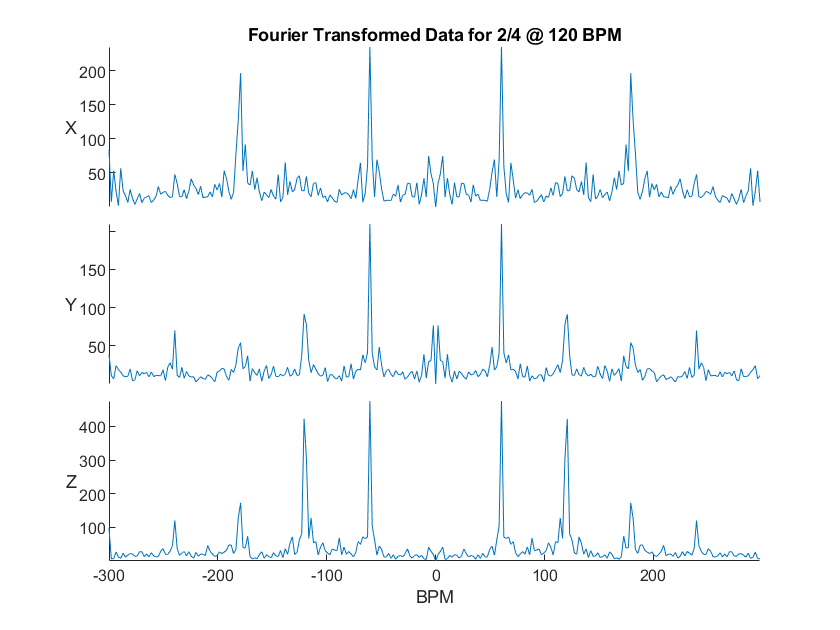

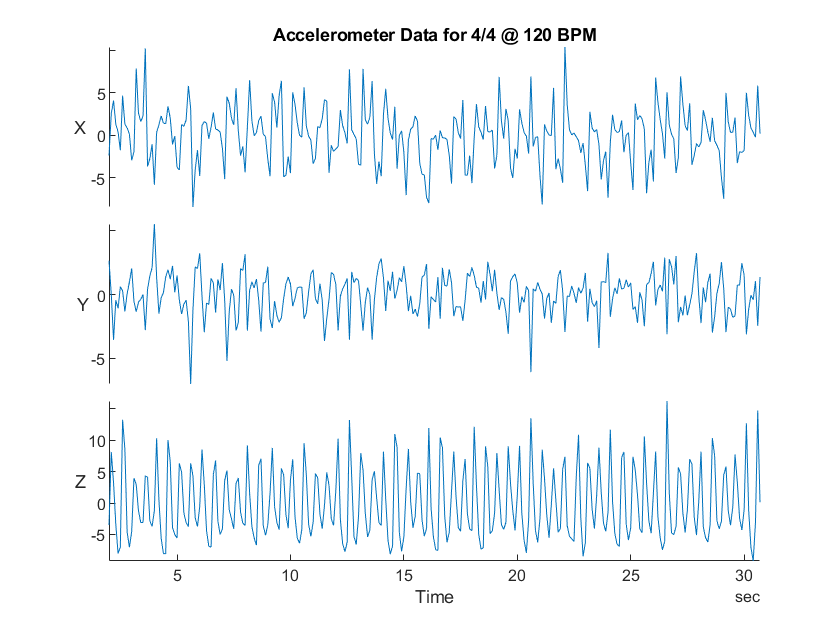

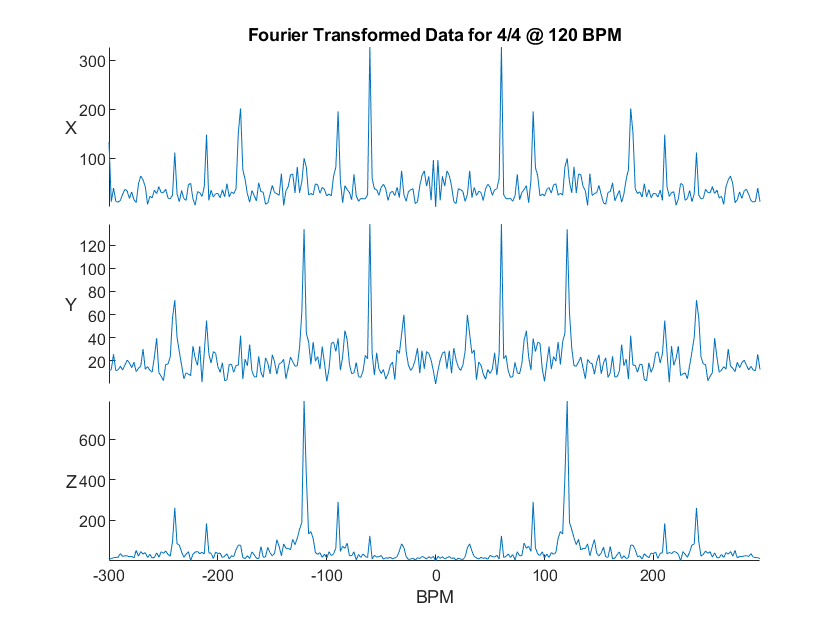

load("all_data.mat");

fields = fieldnames(all_data);
for i = 1:length(fields)    % iterate through each trial
    dataset_title = fields(i);  % get the name of the current trial
    dataset_title = dataset_title{1,1};     % convert name from 1x1 cell to a string
    
    data_i = all_data.(dataset_title).Acceleration; % get acceleration time table for current trial
    [data_i, Fs] = preprocAccelData(data_i, [2,2]); % trim and mean-center the data
    
    % plot the data in the time domain
    figure;
    stackedplot(timetable(seconds(data_i(:,1)), data_i(:,2), data_i(:,3), data_i(:,4), 'VariableNames',{'X','Y','Z'}));
    title(sprintf('Accelerometer Data for %s', dataNameToPlotTitle(dataset_title)));
    
    % fft all data
    N = length(data_i);
    f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N, 2);
    fft_data = abs(fftshift(fft(data_i(:,2:4)),1));

    % format everything into a table so stackedplot can work nicely
    xyz_table = table(f', f'.*60, fft_data(:,1), fft_data(:,2), fft_data(:,3), 'VariableNames',{'Frequency (Hz)', 'BPM', 'X', 'Y', 'Z'});
    
    % plot the data in the frequency domain
    figure;
    stackedplot(xyz_table, {'X', 'Y', 'Z'}, 'XVariable','BPM'); % plot the data in the frequency domain
    title(sprintf('Fourier Transformed Data for %s', dataNameToPlotTitle(dataset_title)));
    
end